clc % clear command window
clear % clear MATLAB workspace
imaqreset % clear all iamge objects

**Set up robot control system **


% Connect to raspi
    robotPi = raspi('192.168.16.71', 'pi', 'raspberry');
% Create connection to the V2 Pi Camera
    robotCam = cameraboard(robotPi, 'Resolution', '1280x720');
    
% Fix auto exposure problem set it to manual, set exposure to work in lab
% lighting. Set whitebalance to manual too. Auto exposure and white balance
% drive computer vision algorithm crazy
    SETUPPICAMERA(robotCam);
 

[centroids, targetArea, cleanImage] = SENSE(robotCam);    

area = 22318

camtest = input('move objects to new position, type G, then hit ENTER', 's');
clc;
imaqreset;

% FIND HOLE AND PLOT IT
hole_center_x = FIND_HOLE(cleanImage)

hole_center_x = 342.7500


camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
figure(camWindow) % go to camWindow for imshow
imshow(cleanImage)
hold on
sz = size(cleanImage)

sz =          720        1280


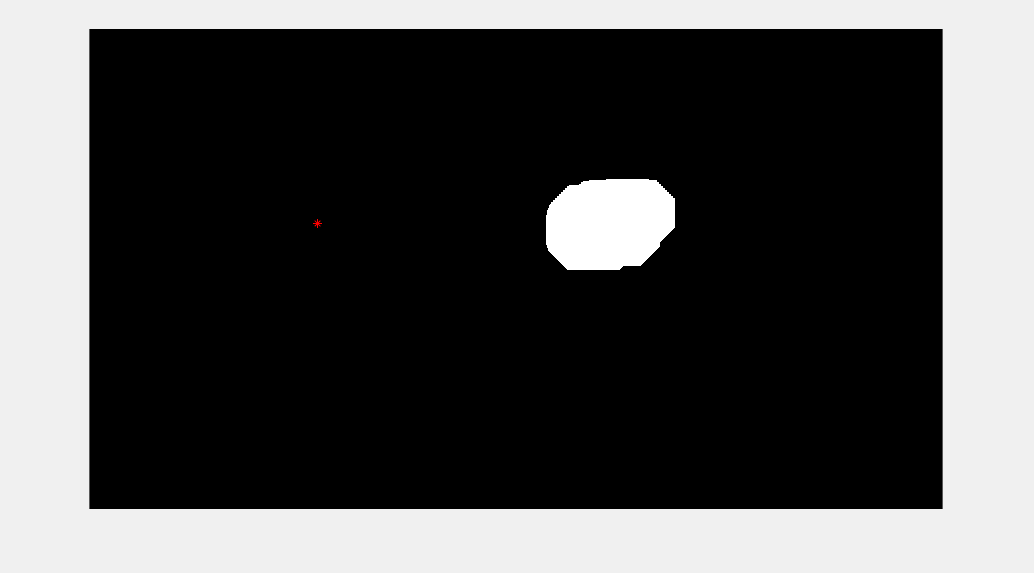


plot(hole_center_x,centroids(2),'r*')
hold off


% FIND BEARING and DISTANCE
[bearing_deg] = FIND_BEARINGS_AND_DISTANCE(targetArea.Area,hole_center_x)

bearing_deg = 16.3433

FUNCTIONS

function [] =  SETUPPICAMERA(robotCam)    
    % Fix expose to set it to respond quickly, set whitebalance to off
    robotCam.ExposureMode = 'night';
    robotCam.AWBMode = 'fluorescent';
end

function [centroids, targetArea, cleanImage] = SENSE(robotCam)
    % This function acquires a single image from the USBCamera testCam and
    % finds and returns centroids of purple area in image
    
    imaqreset;
    % capture image
    robotImage = snapshot(robotCam);
    
    % use color threshold app to create a colormask funciton ( purplemaks)
    % functions will have different anems depending on color of traget
    [targetMask, Img] = redMask(robotImage);
    camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
    figure(camWindow)
    imshow(targetMask)
%     camtest = input('check out masked image,type G, hit Enter','s');
    clc;
    
    % Preprocess image to remove noise
    se = strel('disk',50);
    cleanImage = imopen(targetMask, se); %structure element erosion function
    camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
    figure(camWindow)
    imshow(cleanImage)
%     camtest = input('check out cleaned image, type G, then hit enter',"s")
    clc;
    
    %calculate the centroid of the white part of masked area(target)
    targetCenter = regionprops(cleanImage,'centroid');
    %store the x and y coordinates in a two column matrix
    centroids = cat(1,targetCenter.Centroid);
    % Display the original image with the centroid locations superimposed
    camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
    figure(camWindow) % go to camWindow for imshow
    imshow(robotImage)
    hold on
    plot(centroids(:,1),centroids(:,2),'b*')
    text(centroids(:,1),centroids(:,2), 'Target Centroid')
    hold off
%     camtest = input('check out target center, type G, and hit enter','s');
    clc;
    
    % Calculate the area of the target
    targetArea = regionprops(cleanImage,'area');
    area = targetArea.Area
    % Store the x and y coordinates in a two column matrix
    centroids = cat(1,targetCenter.Centroid);
    % Display the binary image with the centroid locations superimposed
%     camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
%     figure(camWindow) % go to camWindow for imshow
%     imshow(robotImage)
    hold on
%     plot(centroids(:,1),centroids(:,2),'b*')
    %plot(centroids(:,1),(centroids(:,2) + 10),num2str(area));
    hold off
%     camtest = input('check out target center, type G, and hit enter','s');
    clc
end


function [dist] = AREA_TO_DISTANCE(pixel_area)
      m =  -0.0004;
      b = 52.2248;
    
    dist = m*pixel_area + b;
end


function [hole_center_x] = FIND_HOLE(cleanImage)

    %calculate the boundingbox
    stats = regionprops(cleanImage,'BoundingBox');
    x = stats.BoundingBox(1);
    h_len = stats.BoundingBox(3);
    x_left = x;
    x_right = x+h_len;
    
    [image_x, image_y] = size(cleanImage);
    
    left_hole = x_left;
    right_hole = image_x - x_right;
    
    
    if left_hole > right_hole
        hole_center_x = left_hole/2;
    else
        hole_center_x = (image_x - right_hole)/2 + right_hole;
    end
end


function [degree] = FIND_BEARINGS_AND_DISTANCE(target_area,hole_center_x)
% finding distance to target

   
    target_distance = AREA_TO_DISTANCE(target_area); % in cm
    % distance between center of hole and center of target
    distance_pixels = 1280/2 - hole_center_x;
    
    % Convert pixels to cm
    distance_cm = distance_pixels*35/819.41;    %35 is distance in cm and 819 is pixel distance.
    % find distance
    
    degree = atand(distance_cm/target_distance);
end